clc; clear; close all;

%% User Inputs
fprintf('Windowed Sinc FIR Filter Design Method\n');

Windowed Sinc FIR Filter Design Method



% Filter length input
N = input('Enter the length of the filter (must be an odd number, e.g., 51): ');
while mod(N, 2) == 0
    fprintf('The filter length must be odd.\n');
    N = input('Please enter an odd number: ');
end

% Cutoff frequency input
%fs = input('Enter the sampling frequency (Hz): ');
fc = input('Enter the cutoff frequency (Hz) ');
fs = 4 * fc;
% while fc <= 0 || fc >= fs/2
%     fprintf('Cutoff frequency must be between 0 and fs/2.\n');
%     fc = input('Please enter a valid cutoff frequency: ');
% end
wc = 2 * fc / fs; % Normalized cutoff frequency

% Choose display type
fprintf('\nChoose the magnitude response scale:\n');


Choose the magnitude response scale:


fprintf('1. Linear Scale\n');

1. Linear Scale


fprintf('2. Logarithmic Scale (dB)\n');

2. Logarithmic Scale (dB)


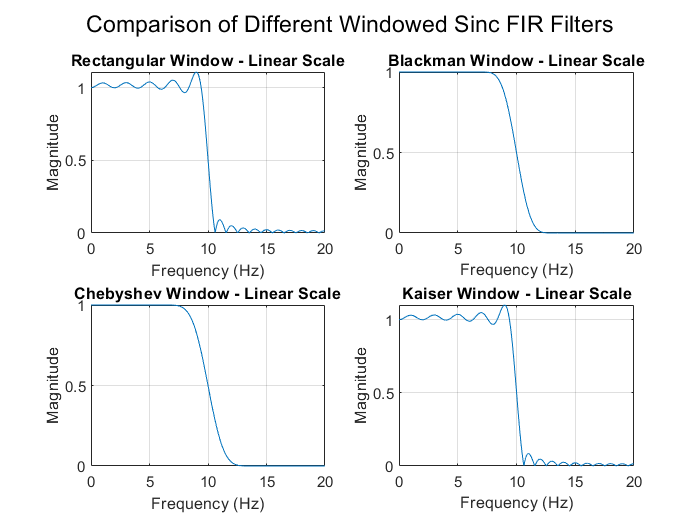

scale_choice = input('Enter 1 or 2: ');

%% Window Functions
% Rectangular Window
rect_win = ones(1, N);

% Blackman Window
blackman_win = blackman(N)';

% Chebyshev Window
%ripple = 60; 
cheby_win = chebwin(N)';

% Kaiser Window
%beta = 6; 
kaiser_win = kaiser(N)';

% Store window names and values
window_types = {'Rectangular', 'Blackman', 'Chebyshev', 'Kaiser'};
windows = {rect_win, blackman_win, cheby_win, kaiser_win};


% figure;
% subplot(3,1,1);
% plot(blackman_win, 'LineWidth', 1.5);
% title('Blackman Window');
% grid on;
% 
% subplot(3,1,2);
% plot(cheby_win, 'LineWidth', 1.5);
% title('Chebyshev Window');
% grid on;
% 
% subplot(3,1,3);
% plot(kaiser_win, 'LineWidth', 1.5);
% title('Kaiser Window');
% grid on;
% sgtitle('Window Functions');


%% Sinc Filter Design
% Generate sinc function
n = -(N-1)/2:(N-1)/2; % Symmetric indices
sinc_func = sin(wc * pi * n) ./ (pi * n); % Sinc function
sinc_func((N-1)/2 + 1) = wc; 

%% Design and Plot Filters
figure;
for i = 1:4
    % Apply window to sinc function
    h = sinc_func .* windows{i};
    
    % Normalize filter gain
    h = h / sum(h);
    
    % Plot magnitude response
    [H, f] = freqz(h, 1, 1024, fs);
    
    subplot(2, 2, i);
    if scale_choice == 1
        plot(f, abs(H));
        title([window_types{i}, ' Window - Linear Scale']);
        ylabel('Magnitude');
    else
        plot(f, 20*log10(abs(H)));
        title([window_types{i}, ' Window - Logarithmic Scale']);
        ylabel('Magnitude (dB)');
    end
    xlabel('Frequency (Hz)');
    grid on;
    ylim auto; % Ensures proper scaling
end

sgtitle('Comparison of Different Windowed Sinc FIR Filters');

fprintf('\nThe magnitude response of the filters has been plotted.\n');


The magnitude response of the filters has been plotted.


% DSP Course Project - FIR Filter Design Tool
% Least Squares (LS) and Weighted Least Squares (WLS) FIR Filter Design

clc; clear; close all;

%% LS & WLS Filter Parameters Inputs
disp('=== FIR Filter Design: LS and WLS Methods ===');

=== FIR Filter Design: LS and WLS Methods ===



% L = input('Enter the length of the filter impulse response: '); % Filter length
% N = input('Enter the number of points in the desired frequency response: '); % Frequency points

% W_pass = input('Enter the weight for the passband region: '); % Passband weight
% W_stop = input('Enter the weight for the stopband region: '); % Stopband weight

%% Hardcoded Inputs for LS Testing
L = 32;              % Filter length (Impulse response length)
N = 512;             % Number of points in the desired frequency response

% Desired frequency response
f = linspace(0, 1, N); % Normalized frequency (0 to 1)

% Hd = input('Enter the desired frequency response vector (same size as N): ');
Hd(f <= 0.4) = 1;    % Passband (0 to 0.4 normalized frequency)
Hd(f >= 0.6) = 0;    % Stopband (0.6 to 1 normalized frequency)

%% Hardcoded Inputs for WLS Testing
disp('For WLS Method: Specify the weights in the frequency regions.');

For WLS Method: Specify the weights in the frequency regions.



W_pass = 1;  % Passband weight
W_stop = 10;   % Stopband weight

% Weight vector (passband = [0 - 0.4], stopband = [0.6 - 1])
W = ones(1, N); 
W(f <= 0.4) = W_pass;  % Weight in passband
W(f >= 0.6) = W_stop;  % Weight in stopband

%% LS FIR Filter Design
disp('Designing FIR filter using Least Squares (LS)...');

Designing FIR filter using Least Squares (LS)...



A = zeros(N, L);
for k = 1:N
    for n = 1:L
        A(k, n) = exp(-1i * 2 * pi * f(k) * (n-1)); % Basis functions
    end
end

% Solve for LS filter coefficients
h_LS = real(pinv(A) * Hd.'); % Least Squares Solution

% Frequency Response of LS Filter
[H_LS, w] = freqz(h_LS, 1, N);
disp('LS filter design complete.');

LS filter design complete.



%% WLS FIR Filter Design
disp('Designing FIR filter using Weighted Least Squares (WLS)...');

Designing FIR filter using Weighted Least Squares (WLS)...



W_diag = diag(W); % Weight matrix
h_WLS = real(pinv(A' * W_diag * A) * (A' * W_diag * Hd.')); % Weighted LS Solution
disp('WLS filter design complete.');

WLS filter design complete.


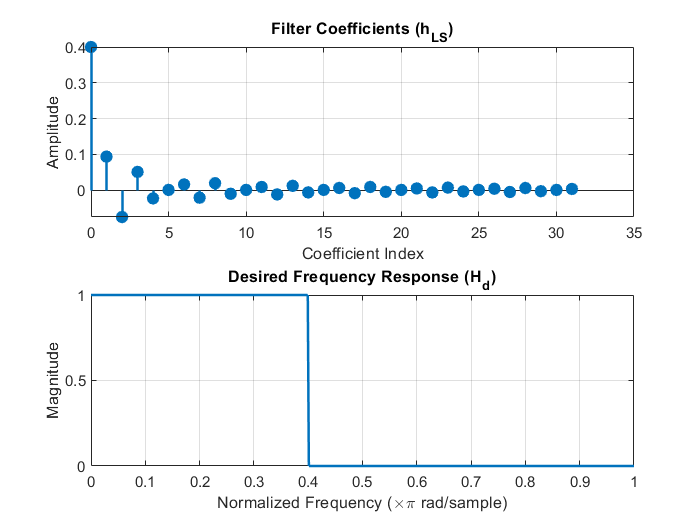


% Frequency Response of WLS Filter
[H_WLS, ~] = freqz(h_WLS, 1, N);

%% Display: Subplot of Filter Coefficients and Desired Response
figure;
% Subplot 1: Filter Coefficients
subplot(2,1,1);
stem(0:L-1, h_LS, 'filled', 'LineWidth', 1.5);
title('Filter Coefficients (h_{LS})');
xlabel('Coefficient Index');
ylabel('Amplitude');
grid on;

% Subplot 2: Desired Frequency Response Hd
subplot(2,1,2);
plot(f, Hd, 'LineWidth', 1.5);
title('Desired Frequency Response (H_d)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
grid on;

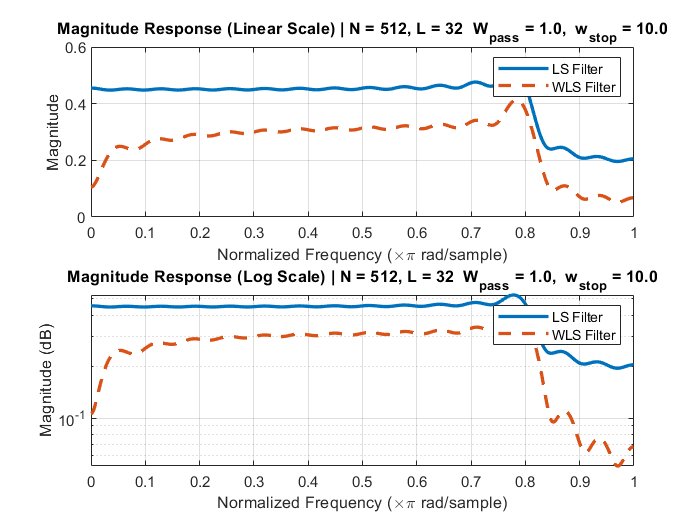


%% Display: Frequency Response Plots (Linear and Log Scale)
% Subplot 1: Linear Scale LS and WLS
figure;
subplot(2,1,1);
plot(w/pi, abs(H_LS), 'LineWidth', 2); hold on;
plot(w/pi, abs(H_WLS), '--', 'LineWidth', 2);
title(sprintf('Magnitude Response (Linear Scale) | N = %d, L = %d  W_{pass} = %.1f,  w_{stop} = %.1f', N, L, W_pass, W_stop));
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
legend('LS Filter', 'WLS Filter');
grid on;

% Subplot 2: Log Scale LS and WLS
subplot(2,1,2);
semilogy(w/pi, abs(H_LS), 'LineWidth', 2); hold on;
semilogy(w/pi, abs(H_WLS), '--', 'LineWidth', 2);
title(sprintf('Magnitude Response (Log Scale) | N = %d, L = %d  W_{pass} = %.1f,  w_{stop} = %.1f', N, L, W_pass, W_stop));
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
legend('LS Filter', 'WLS Filter');
grid on;


disp('Plots are displayed: LS and WLS Magnitude Response.');

Plots are displayed: LS and WLS Magnitude Response.


%  1: Read the audio signal file
[audio, fs] = audioread('gtr-nylon22.wav'); % Replace 'audio_file.wav' with your file
disp(fs);

       22050



%%listening to the audio signal before adding the interfernece and upsampling:-
% sound(audio,fs)
%`fs` is the original sampling frequency based on the nyquist theorem as
%it's larger than double the highst freq in audio signal





%  2: Upsample the audio signal by a factor L = 2
fs_new = 2 * fs; %since we are using upsampling factor of 2, we should use the double of the original frequency we used in sampling the audio 
%therefore,fs new is double the orginal sampling frequency
disp('fs new =');disp(fs_new)

fs new =
       44100



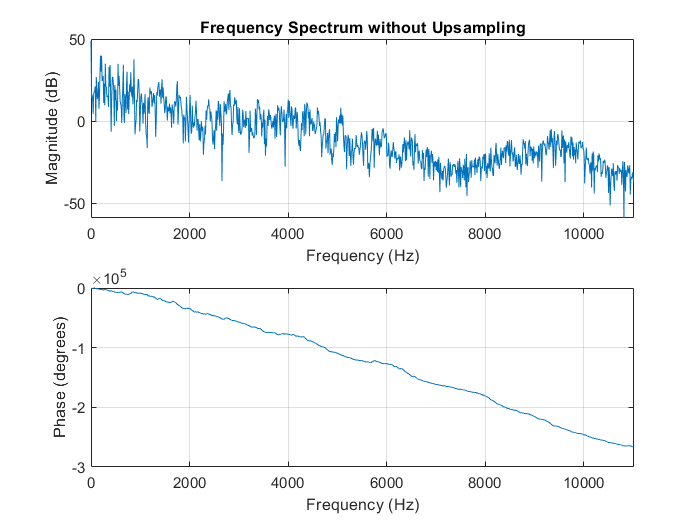




audio_upsampled = resample(audio, 2, 1);

%  3:frequency spectrum before and after upsampling
figure;
subplot(2, 1, 1);
freqz(audio, 1, 1024, fs);%
title('Frequency Spectrum without Upsampling');
subplot(2, 1, 2);

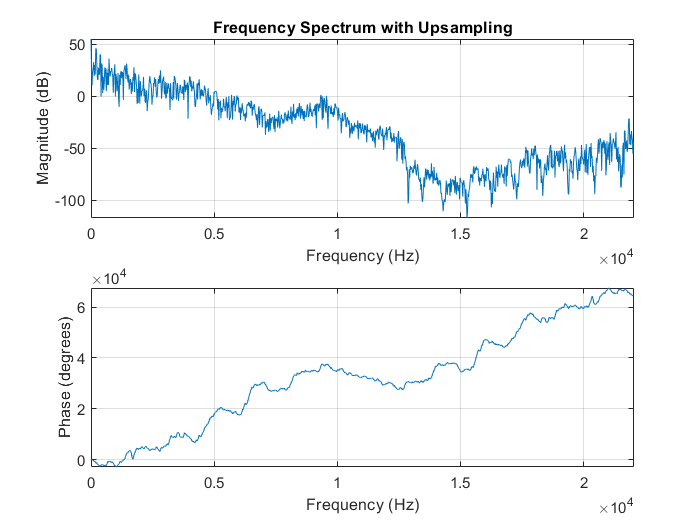

freqz(audio_upsampled, 1, 1024, fs_new);
title('Frequency Spectrum with Upsampling');

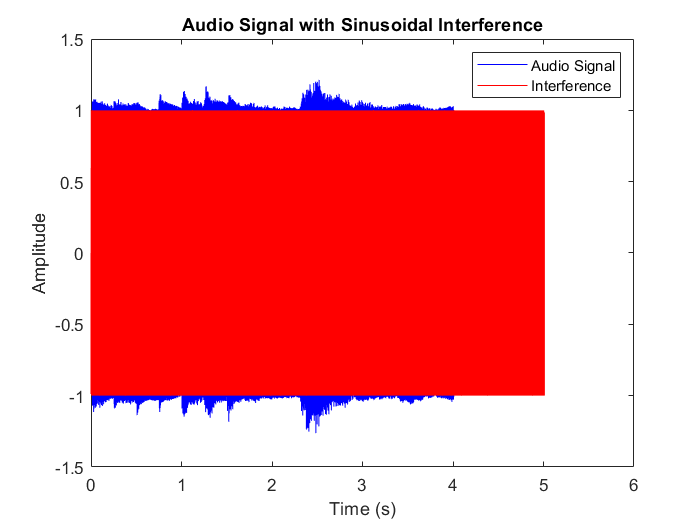

%as seen the audio signal significant freq components lies under 10k
%according to the magnitude, after that there is minimal energy and zero
%energy at higher frequencues that are beyond the nyquist frequence,since
%the interference freq should be less than the nyquist and still doesn't
%overlap with useful signal frequencies, we choose intereference freq.15k

%4
f_interference = 15000;  % Frequency of interference (ensure no overlap with useful audio frequencies)
t = (0:length(audio_upsampled)-1) / fs_new; % Time vector for the upsampled signal

interference =  sin(2 * pi * f_interference * t'); %amplitude scaling for the interference signal by 2, the more the amplitude, noise can be heard
audio_with_interference = audio_upsampled + interference;

figure;
plot(t, audio_with_interference, 'b');
hold on;
plot(t, interference, 'r');
title('Audio Signal with Sinusoidal Interference');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Audio Signal', 'Interference');

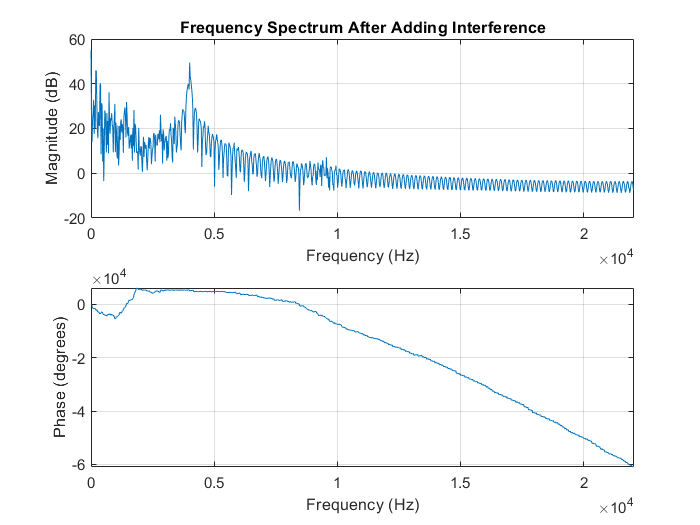

% sound(audio_upsampled,fs_new)

%  5:  frequency spectrum after adding the interference with amplitude=1
figure;
freqz(audio_with_interference, 1, 1024, fs_new);
title('Frequency Spectrum After Adding Interference');



% 6: Listening to the audio  after adding interference(upsampled)

% sound(audio_with_interference, fs_new); %fs_new=2*fs original

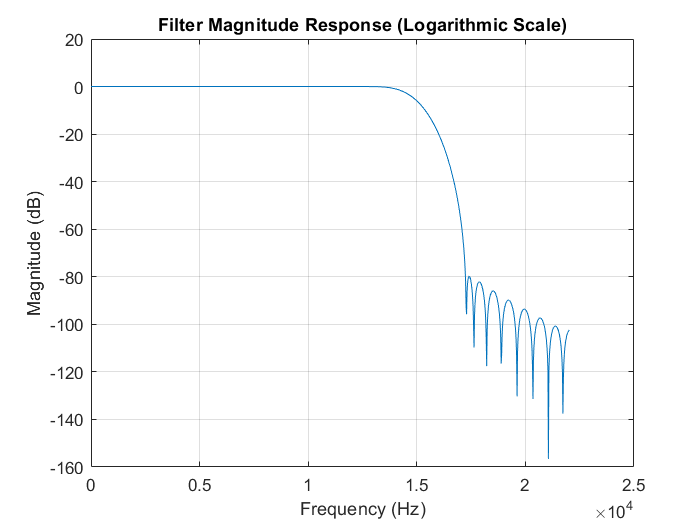

%% 7: Design a Digital FIR Filter
% Using Windowed Sinc FIR Filter Design (example with Kaiser window)

N = 51; % Filter length (odd number)
fc_interference = 15000; % Cutoff frequency to remove interference
wc_interference = 2 * fc_interference / fs_new; % Normalized cutoff frequency
n = -(N-1)/2:(N-1)/2; % Symmetric indices

% Generate Sinc function
sinc_func = sin(wc_interference * pi * n) ./ (pi * n);
sinc_func((N-1)/2 + 1) = wc_interference; % Handle division by zero

kaiser_win = kaiser(N, 8)'; % Kaiser window with beta = 8
cheby_win = chebwin(N)';
rect_win = ones(1, N);
blackman_win = blackman(N)';

h_filter = sinc_func .* kaiser_win; % Apply window
h_filter = h_filter / sum(h_filter); % Normalize filter gain

% Plot filter magnitude response
figure;
% use adham filters (h_LS,h_WLS)
%[H, f] = freqz(h_WLS, 1, 1024, fs_new);
% use amr filters 
[H, f] = freqz(h_filter, 1, 1024, fs_new);
plot(f, 20*log10(abs(H)));
title('Filter Magnitude Response (Logarithmic Scale)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

%% 8: Filter the Audio Signal with Interference
% Filter the audio signal iteratively
audio_filtered0 = filter(h_filter, 1, audio_with_interference);
% 
audio_filtered1 = filter(h_filter, 1, audio_filtered0);

audio_filtered2 = filter(h_filter, 1, audio_filtered1);

audio_filtered3 = filter(h_filter, 1, audio_filtered2);

audio_filtered = filter(h_filter, 1, audio_filtered3);


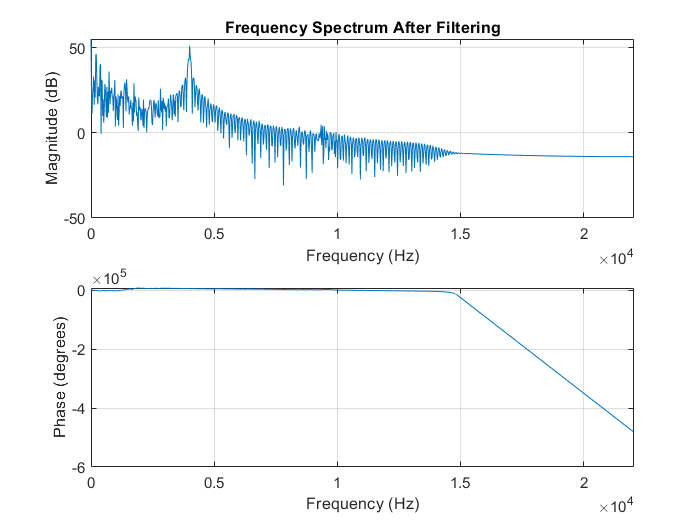

%% 9: Plot Frequency Spectrum After Filtering
figure;
freqz(audio_filtered, 1, 1024, fs_new);
title('Frequency Spectrum After Filtering');

%% 10: Listen to the Audio After Filtering
 sound(audio_filtered, fs_new);

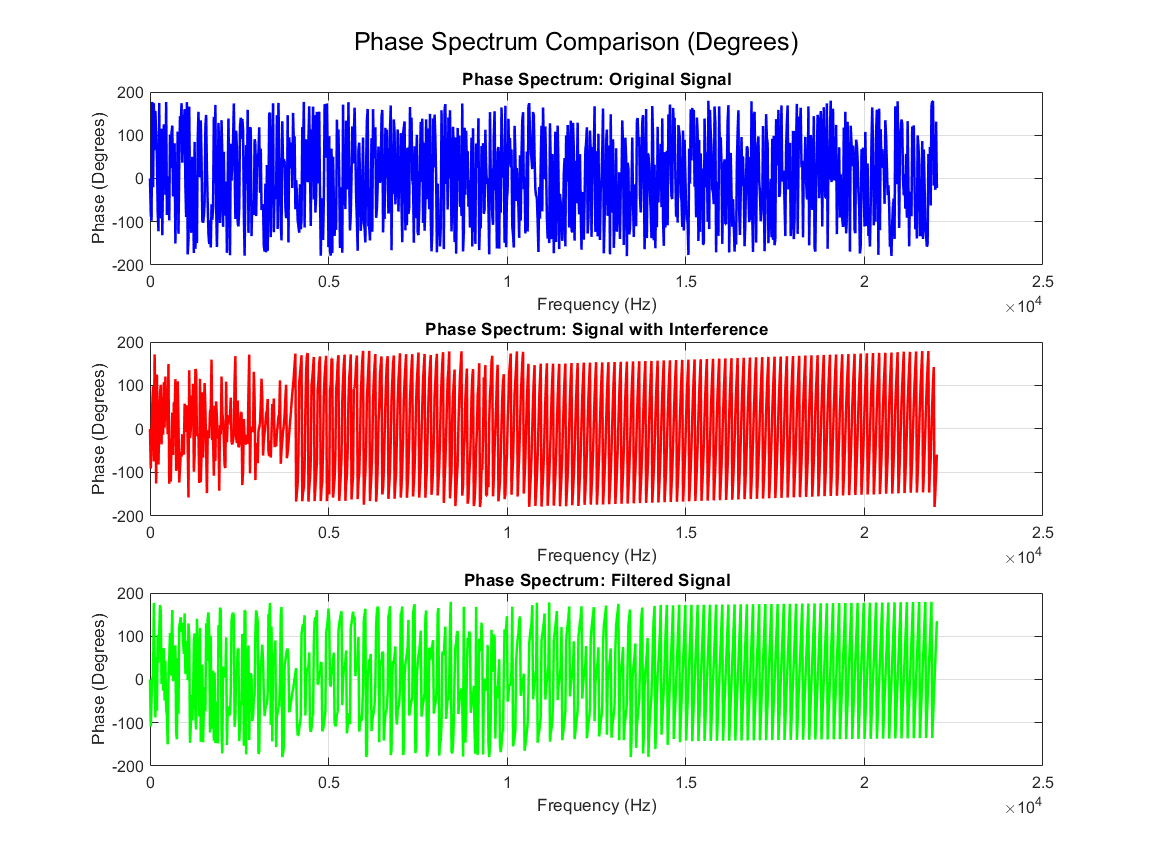

% Set up the figure with a wider layout
figure('Units', 'normalized', 'Position', [0.1 0.1 0.6 0.8]);

% Frequency response of the original signal
[H_original, w] = freqz(audio, 1, 1024, fs_new);

% Frequency response of the interference-added signal
[H_interference, ~] = freqz(audio_with_interference, 1, 1024, fs_new);

% Frequency response of the filtered signal
[H_filtered, ~] = freqz(audio_filtered, 1, 1024, fs_new);

% Convert phase to degrees
phase_original = rad2deg(angle(H_original));
phase_interference = rad2deg(angle(H_interference));
phase_filtered = rad2deg(angle(H_filtered));

% Subplot 1: Original Signal Phase
subplot(3, 1, 1);
plot(w, phase_original, 'b', 'LineWidth', 1.5);
title('Phase Spectrum: Original Signal');
xlabel('Frequency (Hz)');
ylabel('Phase (Degrees)');
grid on;

% Subplot 2: Interference-Added Signal Phase
subplot(3, 1, 2);
plot(w, phase_interference, 'r', 'LineWidth', 1.5);
title('Phase Spectrum: Signal with Interference');
xlabel('Frequency (Hz)');
ylabel('Phase (Degrees)');
grid on;

% Subplot 3: Filtered Signal Phase
subplot(3, 1, 3);
plot(w, phase_filtered, 'g', 'LineWidth', 1.5);
title('Phase Spectrum: Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Phase (Degrees)');
grid on;

% Add a super title for the entire figure
sgtitle('Phase Spectrum Comparison (Degrees)');

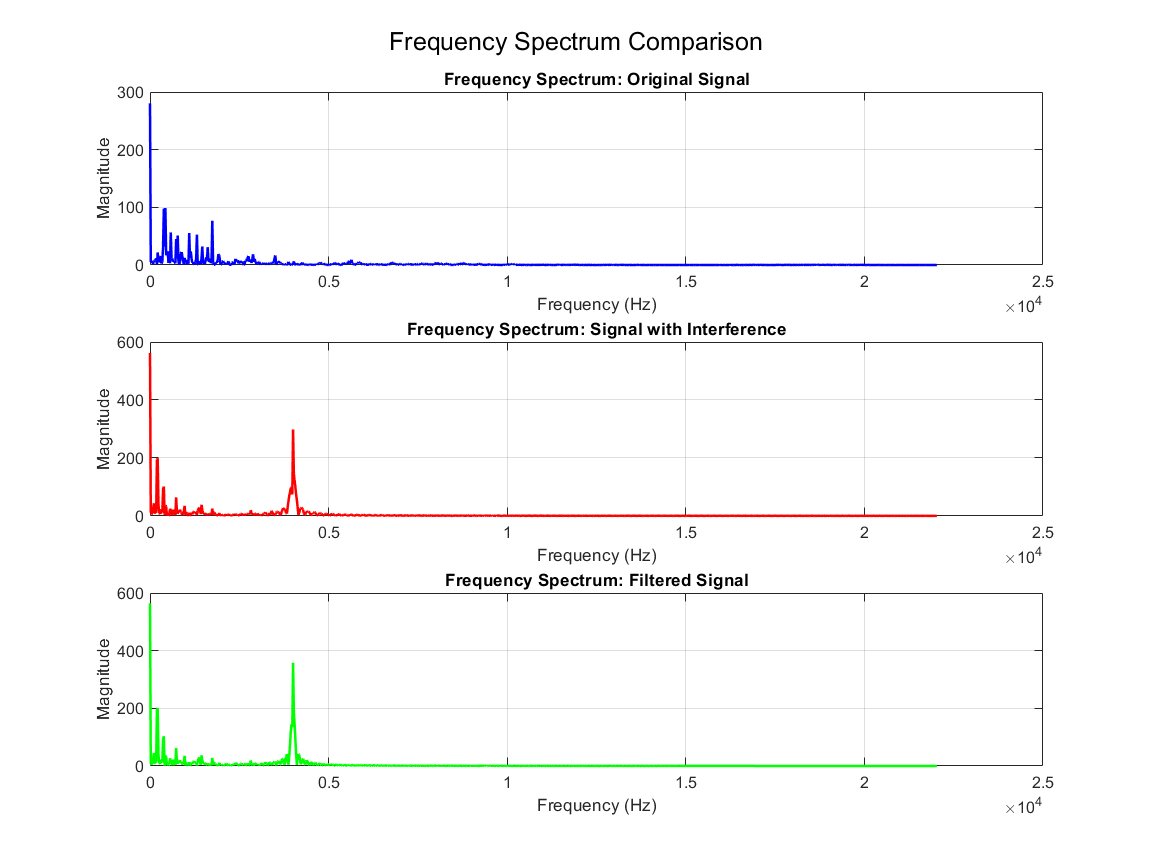

% Set up the figure with a wider layout
figure('Units', 'normalized', 'Position', [0.1 0.1 0.6 0.8]);

% Frequency response of the original signal
[H_original, w] = freqz(audio, 1, 1024, fs_new);

% Frequency response of the interference-added signal
[H_interference, ~] = freqz(audio_with_interference, 1, 1024, fs_new);

% Frequency response of the filtered signal
[H_filtered, ~] = freqz(audio_filtered, 1, 1024, fs_new);

% Subplot 1: Original Signal
subplot(3, 1, 1);
plot(w, abs(H_original), 'b', 'LineWidth', 1.5);
title('Frequency Spectrum: Original Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% Subplot 2: Interference-Added Signal
subplot(3, 1, 2);
plot(w, abs(H_interference), 'r', 'LineWidth', 1.5);
title('Frequency Spectrum: Signal with Interference');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% Subplot 3: Filtered Signal
subplot(3, 1, 3);
plot(w, abs(H_filtered), 'g', 'LineWidth', 1.5);
title('Frequency Spectrum: Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% Add a super title for the entire figure
sgtitle('Frequency Spectrum Comparison');